# NormalDistribution

Makes random samples from a normal distribution, fits to derive parameter estimates, and plots the sample distribution, parent distribution function, and estimated distribution function. 

Author: D. Carlsmith

Setup values for parameters

clear;delete(findall(0,'Type','figure'))%
mu = 0;% mean of normal distribution
sigma = 1;% standard deviation
x=[-4:.1:4]*sigma;% points within 4 standard deviations
nsample = 100;% number of samples to generate

Create a loop to repeat the entire experiment, clearing out figures each time, to look at fluctuations.

ntimes=10;
for ii=1:ntimes    

Calculate and plot normal probability distribution function (pdf) using [normpdf](https://www.mathworks.com/help/stats/normpdf.html).

    y = normpdf(x,mu,sigma);

Generate samples from a normal distribution using [normrnd](https://www.mathworks.com/help/stats/normrnd.html).

    xs=normrnd(mu,sigma,nsample,1);

Histogram the sample data.

    edges=[-4:3];% fix edges for histogram
    histogram(xs,edges);hold on
    title('Normal distribution sample and fit');xlabel('x');ylabel('dP/dx')

Fit the sample distribution to a normal distribution using [normfit](https://www.mathworks.com/help/stats/normfit.html). which returns an estimated mean, estimated standard deviation, and confidence level information.

    [muHat,sigmaHat,muCI,sigmaCI] = normfit(xs);

Calculate the probability distribution function pdf with  parameters derived from the fit to the sample.

    yf = nsample*normpdf(x,muHat,sigmaHat);

Superpose on the data the actual pdf and the pdf derived from the fit.

    plot(x,nsample*y)% superpose actual pdf
    plot(x, yf)% superpose fit pdf
    legend('Samples','Actual pdf','Fit pdf')

Pause for a second before repeating for another sample.

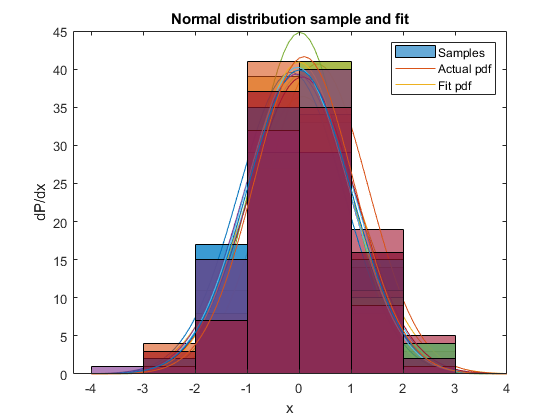

    pause(1);% wait a second
end